# Visualize Volumetric Data with Contour Slices

`contourslice` draws contours at specified slices for volumetric data.

### Create Data

Use the function $v=xe^{\left(-x^2 -y^2 -z^{2\;} \right)} \;$in a helper function to generate volumetric data to illustrate the use of `contourslice`.

[X,Y,Z,V] = createData();

### Basic Contourslice Plot 

Visualize the contours of the volumetric data using `contourslice`. Specify the xslice as 1 to view a volumetric slice at that x plane. View the plot in 3 dimensions.

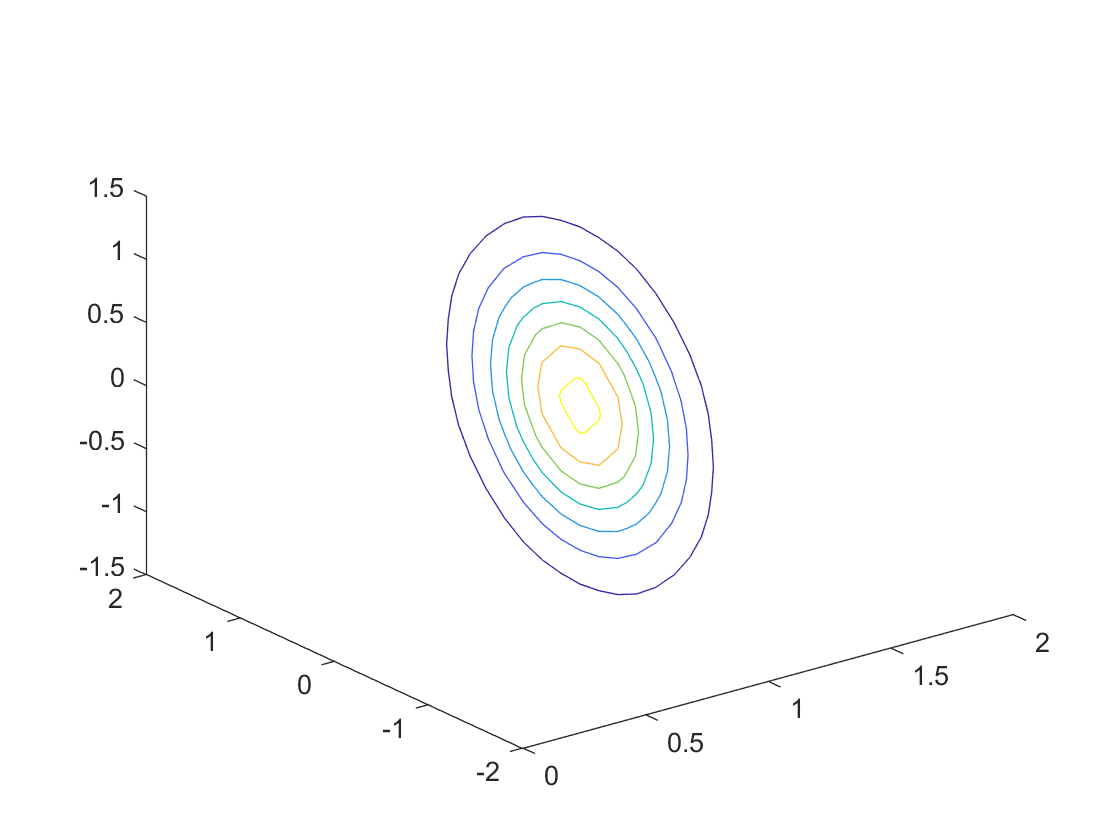

contourslice(X,Y,Z,V,1,[],[])
view(3)

## Customization

### Draw Contours in Several Splice Planes

Specify the interval for multiple slice planes through volumetric data as the 5th input argument to `contourslice`.

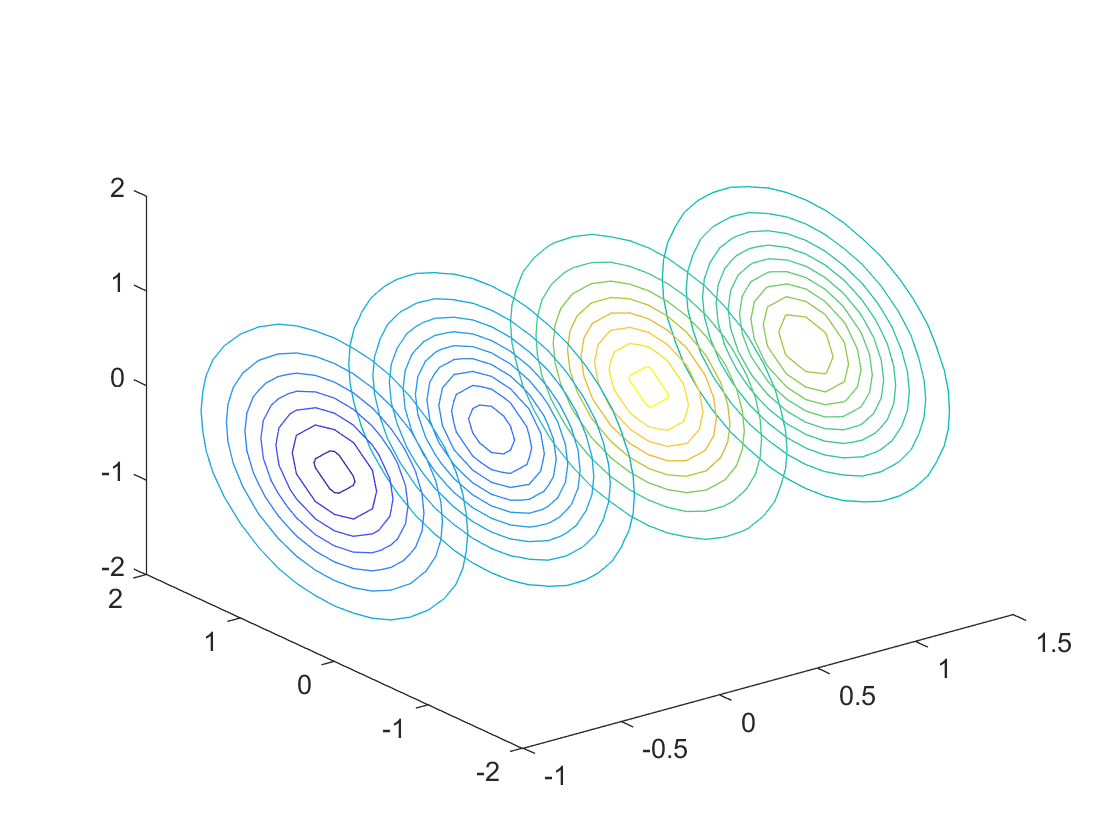

slicePlaneInterval =0.8;
xslice = -1:slicePlaneInterval:2;

figure
c = contourslice(X,Y,Z,V,xslice,[],[]);
view(3)

### Specify Contour Levels and Add Colorbar

Specify a vector of contour levels as the *lvls* argument to `contourslice`. This can increase the number of contour lines for each slice, and help improve the visualization.

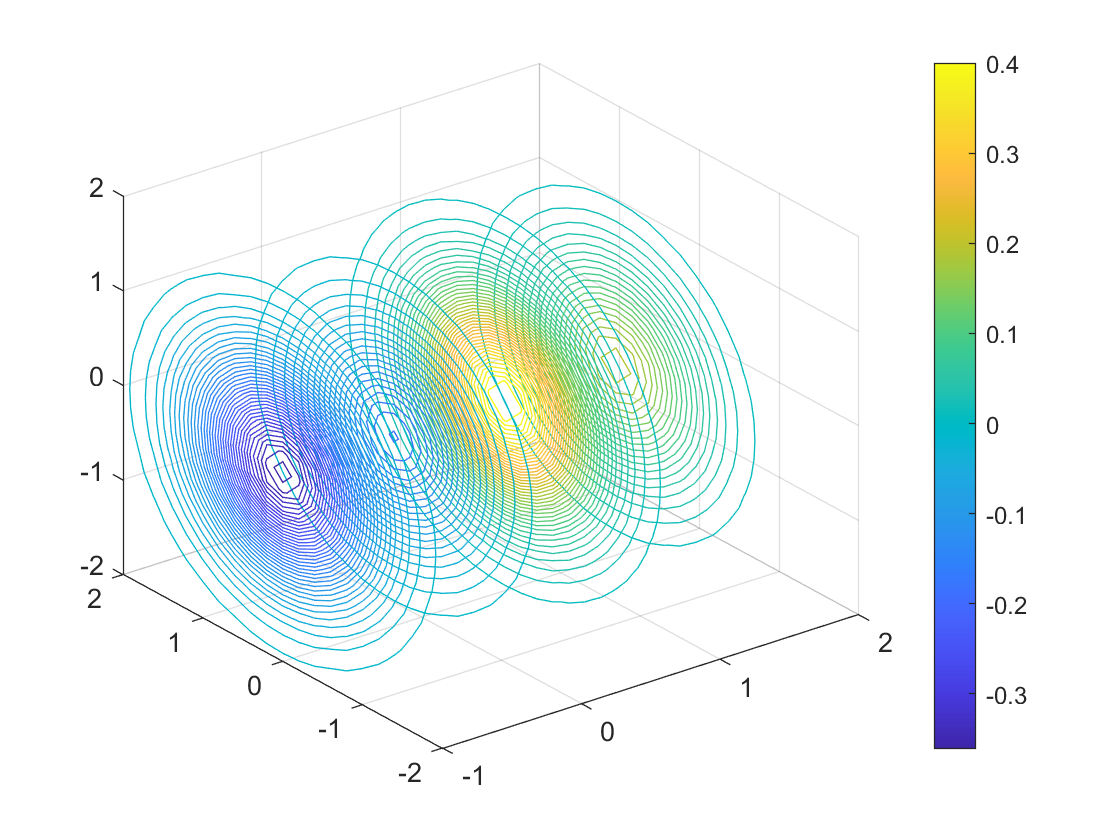

figure
lvls = -0.4:0.01:0.4;
c1 = contourslice(X,Y,Z,V,xslice,[],[],lvls);
view(3)
colorbar
grid on

### Specify Contour Along a Surface Slice

Visualize a slice of the volume data along the surface defined by $z=x^2 -y^{2\;}$. Instead of specifying the contour line levels, use the *num* argument to `contourslice` to specify the number of contour lines desired.

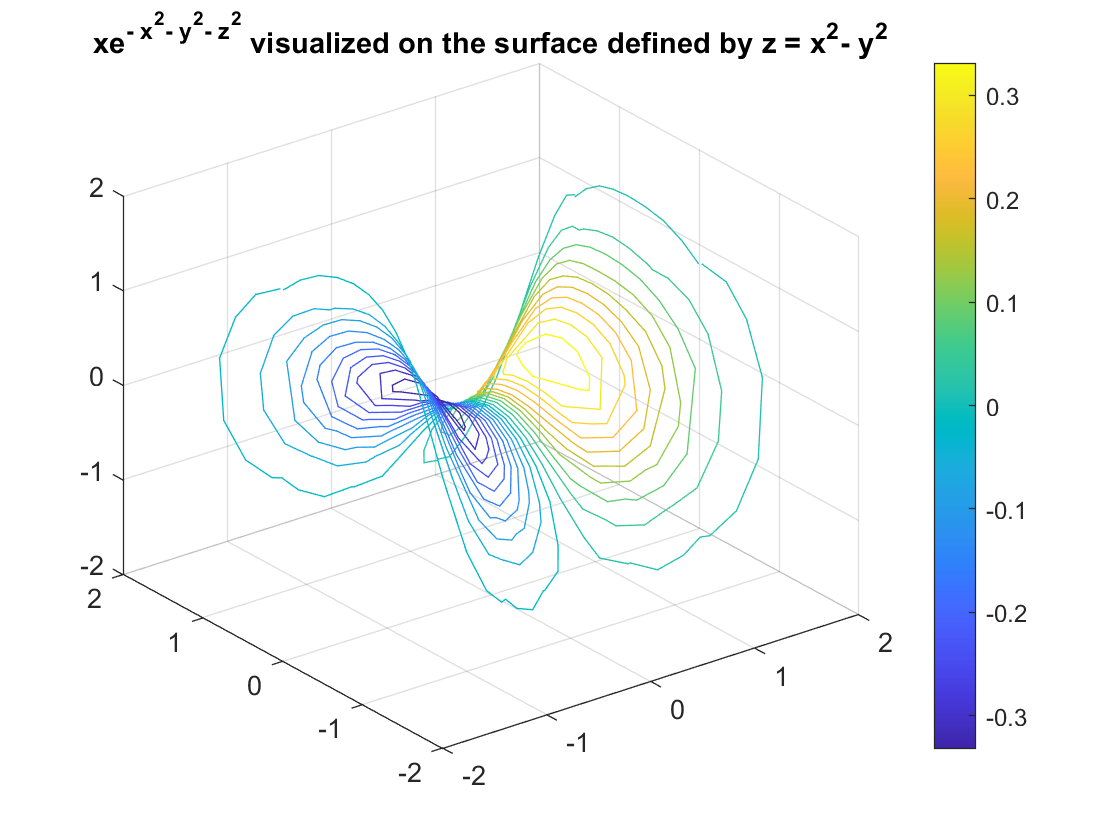

numContours = 20;
[xsurf,ysurf] = meshgrid(-2:0.2:2);
zsurf = xsurf.^2-ysurf.^2;

figure
c2 = contourslice(X,Y,Z,V,xsurf,ysurf,zsurf,numContours);
view(3)
grid on
colorbar
title("xe^{- x^{2}- y^{2}- z^{2}} visualized on the surface defined by z = x^{2}- y^{2}")

### Change Contour Line Width

The call to `contourslice` creates an array of Patch objects. Change the line width of each Patch object using dot notation.

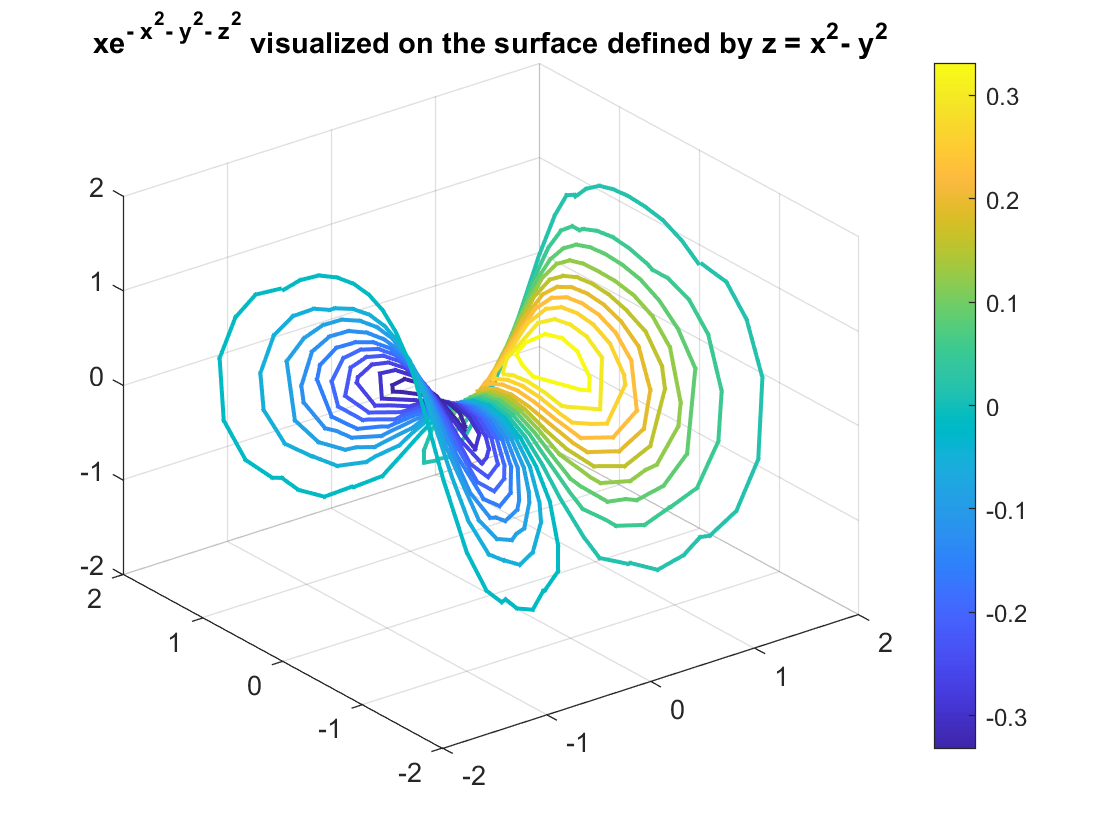

for i = 1:length(c2)
    c2(i).LineWidth =1.5; % Specify the line width of each Patch object using dot notation.
end

## **Additional Information**

### **Get All Patch Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Patch, uncomment the following code. View or modify these properties using dot notation.

% get(c(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[contourslice](https://www.mathworks.com/help/matlab/ref/contourslice.html)

### Helper Functions

This function generates x, y, z and v data with the following relationship: $v=xe^{\left(-x^2 -y^2 -z^{2\;} \right)}$.

function [X,Y,Z,V] = createData()
    [X,Y,Z] = meshgrid(-2:.2:2);
    V = X.*exp(-X.^2-Y.^2-Z.^2);
end


Copyright (c) 2021, The MathWorks, Inc.